%%%%%% Calculation of Maximum Airlight %%%%%%
I =imread('Test1.jpg');
[R,C,K]=size(I);
I=rgb2gray(I)

I = 263×350 uint8 matrix
   172   166   162   186   184   167   180   178   169   168   169   171   170   168   170   173   177   177   176   175   175   175   175   175   169   169   166   163   166   173   175   172   167   170   167   166   180   196   187   165   173   183   180   183   186   158   145   172   171   184
   167   166   166   188   187   173   180   173   168   169   170   171   173   174   174   172   180   175   171   172   178   180   177   173   163   166   167   168   173   177   174   167   171   182   175   160   172   201   200   175   183   184   168   168   184   176   161   171   166   164
   165   173   179   187   174   164   176   174   176   179   178   174   173   175   171   165   181   175   172   177   184   183   174   164   161   164   167   171   175   178   174   169   174   181   174   161   167   187   188   173   184   185   167   160   176   178   166   166   163   159
   188   184   178   173   164   167   176   171   178   184   184   175

%image=I;
imageArray=I(:);
I=im2double(I)

I =     0.6745    0.6510    0.6353    0.7294    0.7216    0.6549    0.7059    0.6980    0.6627    0.6588    0.6627    0.6706    0.6667    0.6588    0.6667    0.6784    0.6941    0.6941    0.6902    0.6863    0.6863    0.6863    0.6863    0.6863    0.6627    0.6627    0.6510    0.6392    0.6510    0.6784    0.6863    0.6745    0.6549    0.6667    0.6549    0.6510    0.7059    0.7686    0.7333    0.6471    0.6784    0.7176    0.7059    0.7176    0.7294    0.6196    0.5686    0.6745    0.6706    0.7216
    0.6549    0.6510    0.6510    0.7373    0.7333    0.6784    0.7059    0.6784    0.6588    0.6627    0.6667    0.6706    0.6784    0.6824    0.6824    0.6745    0.7059    0.6863    0.6706    0.6745    0.6980    0.7059    0.6941    0.6784    0.6392    0.6510    0.6549    0.6588    0.6784    0.6941    0.6824    0.6549    0.6706    0.7137    0.6863    0.6275    0.6745    0.7882    0.7843    0.6863    0.7176    0.7216    0.6588    0.6588    0.7216    0.6902    0.6314    0.6706    0.6510    0

kernel=ones(3)/9;
meanMatrix=conv2(double(I),kernel,'same');
varianceMatrix = stdfilt(I);
varianceArray=varianceMatrix(:);

[minKValues,Indice] = maxk(meanMatrix(:),int16((R*C)/100));
variances=zeros(int16((R*C)/100),2);
for i=1:int16((R*C)/100)
    variances(i,1)=varianceArray(Indice(i));
    variances(i,2)=Indice(i);
end
k=variances

k = 	1.0e+04 *

    0.0000    0.0852
    0.0000    0.1115
    0.0000    0.0851
    0.0000    0.0853
    0.0000    0.1114
    0.0000    1.6331
    0.0000    1.6335
    0.0000    0.3470
    0.0000    1.6332
    0.0000    1.6334


minVariance=min(variances(:,1))

minVariance = 0.0028

minIndices=[];
for i=1:int16((R*C)/100)
    if(variances(i,1)==minVariance)
        minIndices=[minIndices,variances(i,2)];
    end
end
l=minIndices

l = 52998

[X Y]=ind2sub(size(I),l(1))

X = 135

Y = 202

iV=[];
for i=1:numel(minIndices)
   iV=[iV,imageArray(minIndices(i))]; 
end
IV=iV

IV = uint8
211

AirlightMax=max(IV)

AirlightMax = uint8
211

AirlightMaxFloat=double(AirlightMax)/double(255)

AirlightMaxFloat = 0.8275







% Calculation of Minimum Airlight%
I=imread('Test1.jpg');
[R,C,K]=size(I);
I=rgb2gray(I)

I = 263×350 uint8 matrix
   172   166   162   186   184   167   180   178   169   168   169   171   170   168   170   173   177   177   176   175   175   175   175   175   169   169   166   163   166   173   175   172   167   170   167   166   180   196   187   165   173   183   180   183   186   158   145   172   171   184
   167   166   166   188   187   173   180   173   168   169   170   171   173   174   174   172   180   175   171   172   178   180   177   173   163   166   167   168   173   177   174   167   171   182   175   160   172   201   200   175   183   184   168   168   184   176   161   171   166   164
   165   173   179   187   174   164   176   174   176   179   178   174   173   175   171   165   181   175   172   177   184   183   174   164   161   164   167   171   175   178   174   169   174   181   174   161   167   187   188   173   184   185   167   160   176   178   166   166   163   159
   188   184   178   173   164   167   176   171   178   184   184   175

%image=I;
imageArray=I(:);
I=im2double(I)

I =     0.6745    0.6510    0.6353    0.7294    0.7216    0.6549    0.7059    0.6980    0.6627    0.6588    0.6627    0.6706    0.6667    0.6588    0.6667    0.6784    0.6941    0.6941    0.6902    0.6863    0.6863    0.6863    0.6863    0.6863    0.6627    0.6627    0.6510    0.6392    0.6510    0.6784    0.6863    0.6745    0.6549    0.6667    0.6549    0.6510    0.7059    0.7686    0.7333    0.6471    0.6784    0.7176    0.7059    0.7176    0.7294    0.6196    0.5686    0.6745    0.6706    0.7216
    0.6549    0.6510    0.6510    0.7373    0.7333    0.6784    0.7059    0.6784    0.6588    0.6627    0.6667    0.6706    0.6784    0.6824    0.6824    0.6745    0.7059    0.6863    0.6706    0.6745    0.6980    0.7059    0.6941    0.6784    0.6392    0.6510    0.6549    0.6588    0.6784    0.6941    0.6824    0.6549    0.6706    0.7137    0.6863    0.6275    0.6745    0.7882    0.7843    0.6863    0.7176    0.7216    0.6588    0.6588    0.7216    0.6902    0.6314    0.6706    0.6510    0

kernel=ones(3)/9;
meanMatrix=conv2(double(I),kernel,'same');
varianceMatrix = stdfilt(I);
varianceArray=varianceMatrix(:);

[minKValues,Indice] = mink(meanMatrix(:),int16((R*C)/100))

minKValues =     0.0841
    0.0954
    0.0989
    0.0989
    0.1015
    0.1020
    0.1028
    0.1033
    0.1037
    0.1063


Indice =          263
       21040
       21303
       21566
       22092
       22355
       22618
       22881
       21829
       20777


variances=zeros(int16((R*C)/100),2);
for i=1:int16((R*C)/100)
    variances(i,1)=varianceArray(Indice(i));
    variances(i,2)=Indice(i);
end
k=variances

k = 	1.0e+04 *

    0.0000    0.0263
    0.0000    2.1040
    0.0000    2.1303
    0.0000    2.1566
    0.0000    2.2092
    0.0000    2.2355
    0.0000    2.2618
    0.0000    2.2881
    0.0000    2.1829
    0.0000    2.0777


minVariance=min(variances(:,1))

minVariance = 0

minIndices=[];
for i=1:int16((R*C)/100)
    if(variances(i,1)==minVariance)
        minIndices=[minIndices,variances(i,2)];
    end
end
l=minIndices

l = 43395

iV=[];
for i=1:numel(minIndices)
   iV=[iV,imageArray(minIndices(i))]; 
end
IV=iV

IV = uint8
49

AirlightMin=min(IV)

AirlightMin = uint8
49

AirlightMinFloat=double(AirlightMin)/double(255)

AirlightMinFloat = 0.1922



NetAirlightFloat=AirlightMaxFloat-AirlightMinFloat

NetAirlightFloat = 0.6353

NetAirlight=AirlightMax-AirlightMin

NetAirlight = uint8
162

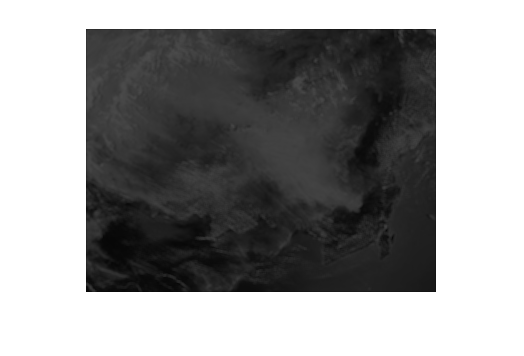


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Dehazing with Net Airlight%%%%%%%%%%%%%%%

I = (imread(['Test1.jpg']));
% imshow(I)
%I=rgb2gray(I);
[r,c,k]=size(I);
rChannel=I(:,:,1);
gChannel=I(:,:,2);
bChannel=I(:,:,3);
rArray=rChannel(:);
gArray=gChannel(:);
bArray=bChannel(:);

minArray=zeros(size(rArray));
for i=1:size(rArray)
   minArray(i)=min([rArray(i),gArray(i),bArray(i)]);
end
B=reshape(minArray,[r,c]);
%imshow(B);

%%% Replace The value of NetAirlight in numeric value as shown in output
fun=@(x) 1-(sqrt(sum(x(:).^2))/(162*3*3));
T = nlfilter(B,[3 3],fun);
%imshow(T);

%%% Replace The value of NetAirlightFloat in numeric value as shown in output
fun2=@(x) 0.6353*(1-(x));
TT=nlfilter(T,[1 1],fun2);
imshow(TT);

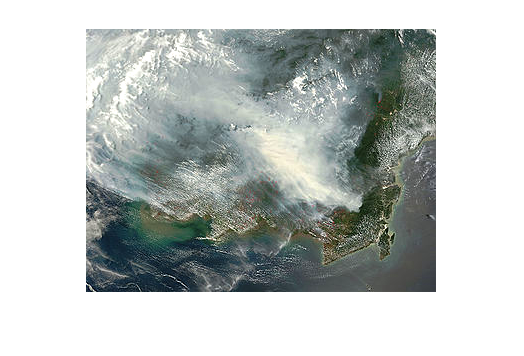

TT=im2double(TT);


r=im2double(rChannel)-im2double(TT);
Jr=im2double(r)./im2double(T);
g=im2double(gChannel)-im2double(TT);
Jg=im2double(g)./im2double(T);
b=im2double(bChannel)-im2double(TT);
Jb=im2double(b)./im2double(T);

rgbImage = cat(3, Jr,Jg,Jb);
imshow(rgbImage)


%%%%% Statistics Measures %%%%%%%
rgbImageGray=rgb2gray(rgbImage);
H=entropy(rgbImageGray)

H = 7.7075

HFilter=[0 0 0;0 1 -1;0 0 0];
HFilterImage=imfilter(rgbImageGray,HFilter);
VFilter=[0 -1 0;0 1 0;0 0 0];
VFilterImage=imfilter(rgbImageGray,VFilter);
HFilterImage=HFilterImage.^2;
VFilterImage=VFilterImage.^2;
HV=HFilterImage+VFilterImage;
HV=HV.^0.5;
S=sum(HV(:));
S=S/(R*C)

S = 0.1076

DeltaRG=Jr-Jg;
DeltaYB=((Jr+Jg).*0.5)-Jb;
MeanRG=mean(DeltaRG(:));
MeanYB=mean(DeltaYB(:));
SdRG=std(DeltaRG(:));
SdYB=std(DeltaYB(:));
C=sqrt((SdRG^2)+(SdYB^2));
C=C+0.3*sqrt((MeanRG^2)+(MeanYB^2))

C = 0.0655